Lisa Jacklin

12/8/2022

# EE 333 Homework 9

Consider an enhancement N-channel MOSFET with the following parameters, KN = 50 µA/V2, VTN = 1.5 V, and 

λ = 0 V-1

Write a MATLAB program that will plot two curves on the ID versus VDS graph

- The ID curve for VGS = 3.5 V

- The boundary of the saturation region.

%the code below are based on a MATLAB example resource.
%this should display the ID curve for VGS = 3.5V
hfin=1;
tsi=20

tsi = 20

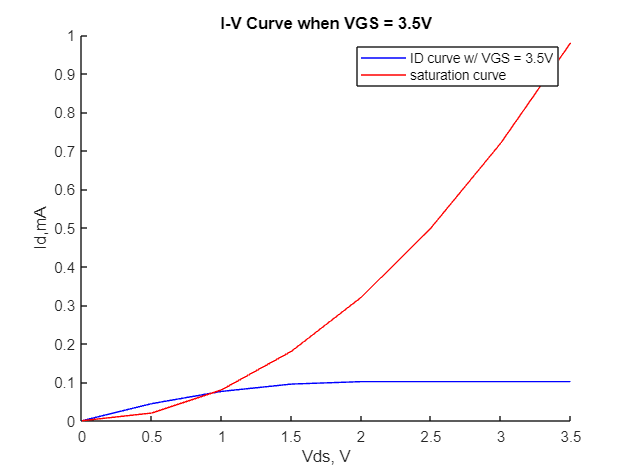

W=2*hfin*tsi;
Vth=1.5;% VTN = 1.5;
Leff=180;
DIBL=1.127*(W\Leff);
vth=Vth-DIBL;
lambda=0;% lambda=0;
u=1360;
ld=0.1;
Ec=1.5*106;
Cox=60;
Vds=0:0.5:10;
vgs=3.5;% VGS=3.5;
m=length(Vds);

%this is the ID curve for VGS = 3.5V
for i=1:m
    if vgs < Vth
        current(1,i)=0;
        current1(1,i)=0;
    elseif Vds(i) >= (vgs - Vth)
        current(1,i)=0.5* DIBL * ((vgs - Vth)^2)*(1+lambda*Vds(i))*1e-2;%Added DIBL
    elseif Vds(i) < (vgs - Vth)
        current(1,i)= DIBL*((vgs-Vth)*Vds(i) - 0.5*(Vds(i)^2))*(1+lambda*Vds(i))*1e-2; %Simplified equation by approximation
    end
end

%saturation curve....
%kn = 80e-3;
y = 80e-3*Vds.^2; %since the saturation curve has units mA/V^2


hold on
    plot(Vds,current(1,:),'b') %to plot the current curve for VGS = 3.5
    plot(Vds, y, 'r') %this should display the saturation curve
hold off

        xlabel('Vds, V')
        xlim([0,3.5]) %better view of the curve
        ylabel('Id,mA')
        ylim([0,1]) %better view of the cross between the saturation and ID curve
        title('I-V Curve when VGS = 3.5V')
        legend( "ID curve w/ VGS = 3.5V","saturation curve")